# Assignment 2-1: SENSE Reconstruction

## SENSE

(SENSitivity Encoding) parallel imaging reconstruction method.

See [here](http://mriquestions.com/senseasset.html) for a basic introduction. See [this review paper](https://www.researchgate.net/publication/8178233_SMASH_SENSE_PILS_GRAPPA_how_to_choose_the_optimal_method) (p.226) for a more detailed explanation.

The notation used in the code below is based on the review paper.

## Loading data

brainCoilsData = load('brain_coil.mat');
brainCoils = brainCoilsData.brain_coil_tmp;

coilMapData = load('coil_sensitivity_map.mat');
coilMap = coilMapData.coil_map;

[phaseLength, freqLength, coilNum] = size(brainCoils);
disp(size(brainCoils));  % Phases, Frequencies, Coil Number

   120   128     5



## Convert to Fourier Domain with 2D Fast Fourier Transform

Remember to use fftshift and ifftshift when using the Fourier Transform. 

Otherwise, the k-space will not be centered properly.

fullKspace = ifftshift(fft2(fftshift(brainCoils)));

Examine raw k-space.

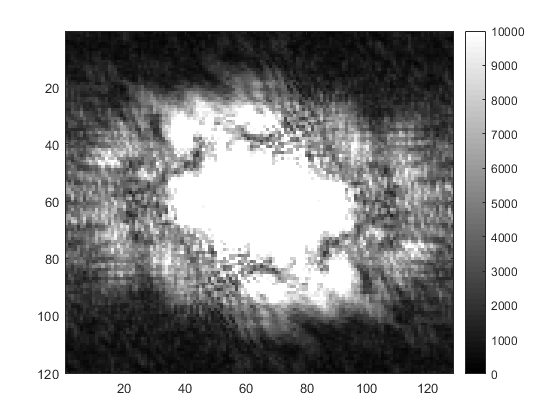

fullKspaceImage = rsos(fullKspace);
figure;
imagesc(fullKspaceImage, [0, 10000]);
colormap('gray');
colorbar();

## Setting parameters for later use.

downSamplingRate = 5;

## Making the mask

Creating a mask for the downsampling and the acs lines.

mask = zeros(size(fullKspace));  % Making a mask for the brain coils.

for line=1:phaseLength  % Goes along the phase encoding axis.
    if rem(line, downSamplingRate) == 0
        mask(line, :, :) = 1;  % Broadcasting the value of 1 to mask(i, :, :).
    end    
end

assert(isequal(size(mask), size(brainCoils)), 'Mask size is incorrect.')

## Displaying mask.

This code functions to check whether the mask has been made correctly.

White lines indicate 1's. Black lines indicate 0's. All values should be either 0 or 1.

There should be a white band in the middle, with striped lines surrounding it.

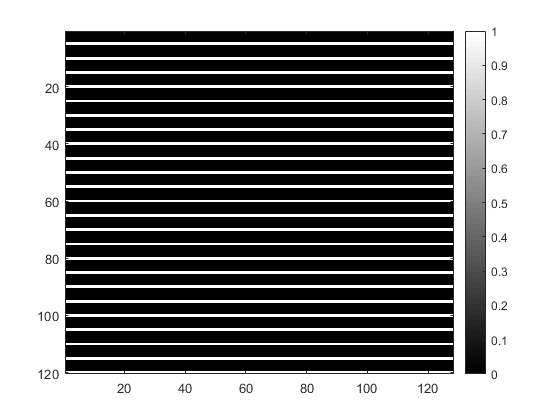

dispMask = mean(mask, 3);
figure;
imagesc(dispMask);
colormap('gray');
colorbar();

## Generating the down-sampled k-space image

Obtain the Hadamard product (elementwise matrix multiplication) between the full k-space data and the mask.

Hint: use the .* operator, not the * operator, which does matrix multiplication.

% Elementwise (Hadamard) product (multiplication) of matrices.
downSampledKspace = fullKspace .* mask;

## Confirmation

Confirming that the masking has been performed properly in k-space.

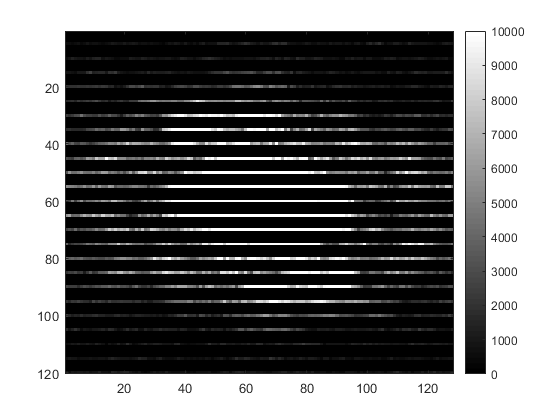

downSampledKspaceImage = rsos(downSampledKspace);
figure;
imagesc(downSampledKspaceImage, [0, 10000]);
colormap('gray');
colorbar();

assert(isequal(size(downSampledKspace), size(brainCoils)), 'Reconstruction is of the wrong shape.')

## Returning the downsampled data to image space.

dsBrainCoils = ifftshift(ifft2(fftshift(downSampledKspace)));
assert(isequal(size(dsBrainCoils), size(brainCoils)), 'Image shape is wrong.');

## Checking reconstructed image.

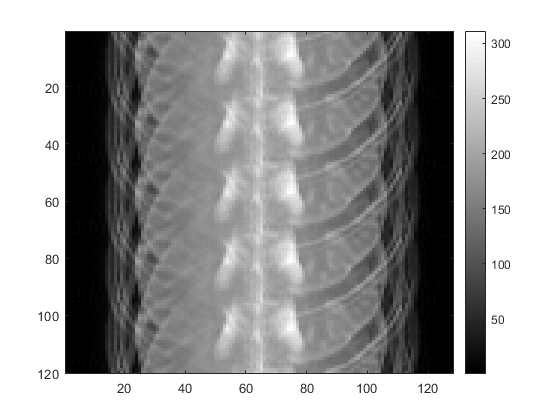

% Using rsos (root sum of squares) to make visualization possible.
dsImage = rsos(dsBrainCoils);
figure;
imagesc(dsImage);
colormap('gray');
colorbar();

## SENSE Reconstruction

fieldOfView = floor(phaseLength/downSamplingRate);  % Not a perfect solution but works for this experiment.
cHat = zeros(coilNum, downSamplingRate);
senseRecon = zeros(phaseLength, freqLength);
vectorI = zeros(coilNum, 1);

for x=1:freqLength
    for y=1:fieldOfView
        vectorI = reshape(dsBrainCoils(y, x, :), coilNum, 1);  % All channels of single pixel in image.
        for k=1:downSamplingRate
            % Coil sensitivities of all channels of a single pixel per segment.
            cHat(:, k) = reshape(coilMap(y+(k-1).*fieldOfView, x, :), coilNum, 1);
        end

        cHatPinv = pinv(cHat);  % Moore-Penrose Pseudoinverse.
        vectorRho = cHatPinv * vectorI;
        
        for k=1:downSamplingRate
            senseRecon(y + (k-1) .* fieldOfView, x) = vectorRho(k);
        end
    end
end

## Visualizing results

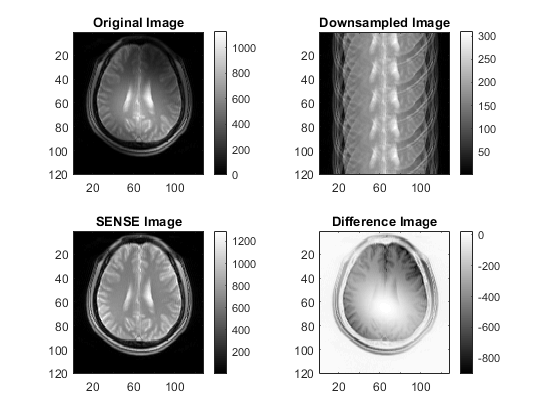

senseImage = rsos(senseRecon);
senseImage = senseImage .* downSamplingRate;  % Necessary to correct for the missing values.
original = rsos(brainCoils);
delta = original-senseImage;

figure;
colormap('gray');

subplot(2, 2, 1);
imagesc(original);
title('Original Image');
colorbar();

subplot(2, 2, 2);
imagesc(dsImage);
title('Downsampled Image');
colorbar();

subplot(2, 2, 3);
imagesc(senseImage);
title('SENSE Image');
colorbar();

subplot(2, 2, 4);
imagesc(delta);
title('Difference Image');
colorbar();